# Expand Example 6.4:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Design a 3rd-order Chebyshev analog lowpass filter with passband edge frequency $\omega_{1}=1$ rad/s and parameter $\varepsilon=0.4$.

% Set design parameters
epsilon = 0.4;
omg1 = 1;  % Critical frqequency
N = 3;     % Filter order
% Create a vector of indices for the Chebyshev filter poles.
k = [0:2*N-1]';
% Compute parameters
alpha_k = (2*k+1)*pi/6

alpha_k =     0.5236
    1.5708
    2.6180
    3.6652
    4.7124
    5.7596


beta = asinh(1/epsilon)/3

beta = 0.5491

% Compute poles of H(s)H(-s)
theta_k = alpha_k+j*beta;
disp('Poles of the filter:');

Poles of the filter


pk = j*cos(theta_k)

pk =    0.2885 + 0.9999i
   0.5771 + 0.0000i
   0.2885 - 0.9999i
  -0.2885 - 0.9999i
  -0.5771 - 0.0000i
  -0.2885 + 0.9999i


% Compute denominator coefficients
disp('Denominator coefficients:');

Denominator coefficients


% Use stable poles for H(s)
den = real(conv([1,-pk(5)],conv([1,-pk(4)],[1,-pk(6)])))

den =     1.0000    1.1542    1.4161    0.6250


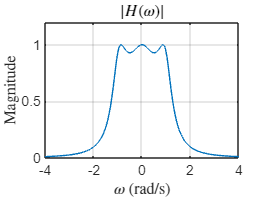

% Compute the frequency response
num = den(4);  % Adjust for unit gain at dc
omg = [-4:0.01:4];
H = freqs(num,den,omg);
% Graph the magnitude and the phase of the frequency response
plot(omg,abs(H)); grid;
set(0,'defaultTextInterpreter','latex');
axis([-4,4,0,1.2]);
xlabel('$\omega$ (rad/s)');
ylabel('Magnitude');
title('$|H(\omega)|$');

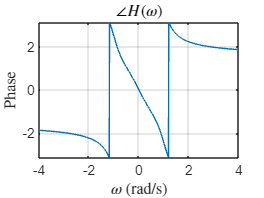

plot(omg,angle(H)); grid;
axis([-4,4,-pi,pi]);
xlabel('$\omega$ (rad/s)');
ylabel('Phase');
title('$\angle H(\omega)$');

set(0,'defaultTextInterpreter','tex');